## Final Modeling Project Draft Notebook

Marcus & Angela

Evolution of a Sandy Coastline

% setting parameters
L = 1000; % length of the domain (m)
T = 10000; % simulation time (s)
D = 1; % diffusivity (m^2/s)
Nx = 100; % number of spatial points
Nt = 500; % number of time steps
dx = L/(Nx -1); % Spatial step size
dt = T/Nt; % time step size

% initial conditions
x = linspace(0, L, Nx);
y = zeros(Nx, 1);
y(1:Nx/2) = linspace(0, 100, Nx/2); % linear initial condition

Figure 1 & 2, Intial vs. Final Coastline Position and Evolution over time

Finite Difference Method (do we need more than one method? how many?)

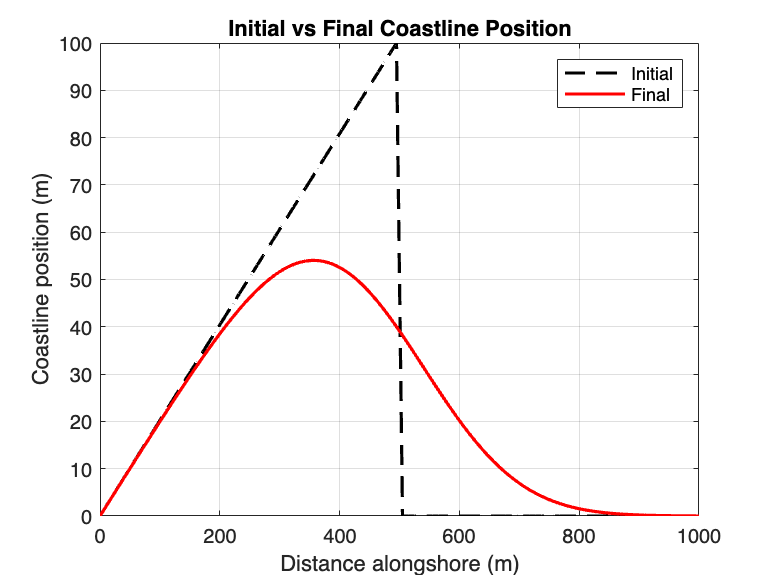

% Initial vs Final Coastline
figure(1);
plot(x, y, 'k--', 'LineWidth', 1.6, 'DisplayName', 'Initial');
hold on;

for n = 1:Nt
    y_new = y;
    for i = 2:Nx-1
        y_new(i) = y(i) + D * dt / dx^2 * (y(i+1) - 2*y(i) + y(i-1));
    end
    y = y_new;
    % save the final state for comparison
    if n == Nt
        plot(x, y, 'r', 'LineWidth', 1.6, 'DisplayName', 'Final');
    end
end
xlabel('Distance alongshore (m)'); ylabel('Coastline position (m)');
title('Initial vs Final Coastline Position'); legend; grid on;

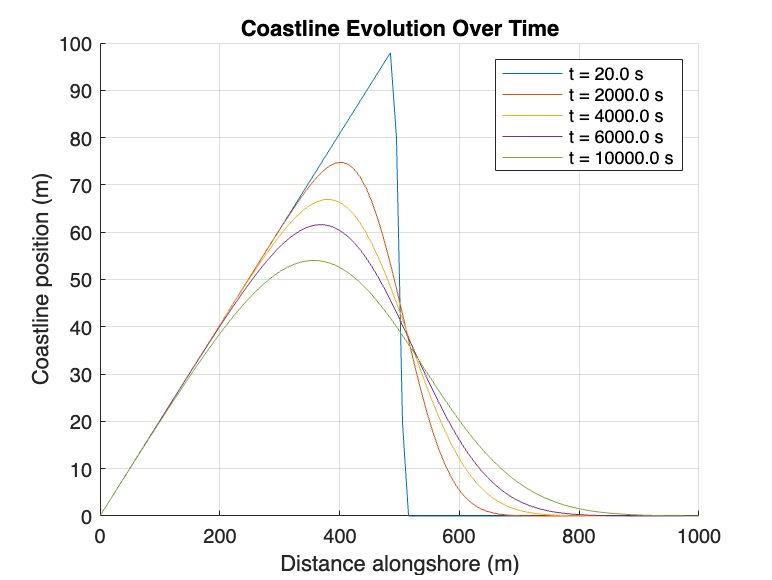


% store shoreline positions at selected time steps for plotting
time_steps_to_plot = [1, 100, 200, 300, Nt];
y_history = zeros(Nx, length(time_steps_to_plot));
plot_index = 1;
% Reset y for evolution plotting
y = zeros(Nx, 1);
y(1:Nx/2) = linspace(0, 100, Nx/2);

for n = 1:Nt
    y_new = y;
    for i = 2:Nx-1
        y_new(i) = y(i)+D*dt/dx^2*(y(i+1)-2*y(i)+y(i-1));
    end
    y = y_new;
    if ismember(n, time_steps_to_plot)
        y_history(:, plot_index) = y;
        plot_index = plot_index + 1;
    end
end

% Plot selected time steps
figure(2);
hold on;
for i = 1:length(time_steps_to_plot)
    plot(x, y_history(:, i), 'DisplayName', sprintf('t = %.1f s', time_steps_to_plot(i) * dt));
end
xlabel('Distance alongshore (m)'); ylabel('Coastline position (m)');
title('Coastline Evolution Over Time'); legend show; grid on;

Figure 3, Effect of Diffusivity on Final Coastline

same methods

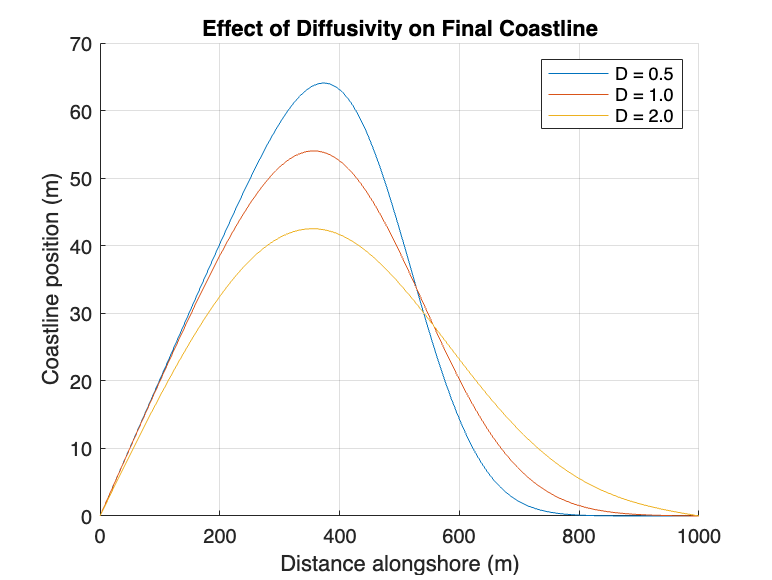

figure(3);
D_values = [0.5, 1, 2]; % different diffusivities
hold on;
for D_test = D_values
    y = zeros(Nx, 1);
    y(1:Nx/2) = linspace(0, 100, Nx/2); % reset initial condition
    for n = 1:Nt
        y_new = y;
        for i = 2:Nx-1
            y_new(i) = y(i)+D_test*dt/dx^2*(y(i+1)-2*y(i)+y(i-1));
        end
        y = y_new;
    end
    plot(x, y, 'DisplayName', sprintf('D = %.1f', D_test));
end
xlabel('Distance alongshore (m)'); ylabel('Coastline position (m)');
title('Effect of Diffusivity on Final Coastline'); legend show; grid on;

We need to figure out two more figures to do